
%% Following instructions from Gard10 readme file
p = tgs_parameters_v10();
p.NG = 100;
p.seed = [153 1 39];
p.sigma = 2.5;
p.Beta = tgs_newbeta_v10(p);
p.gen = 500;


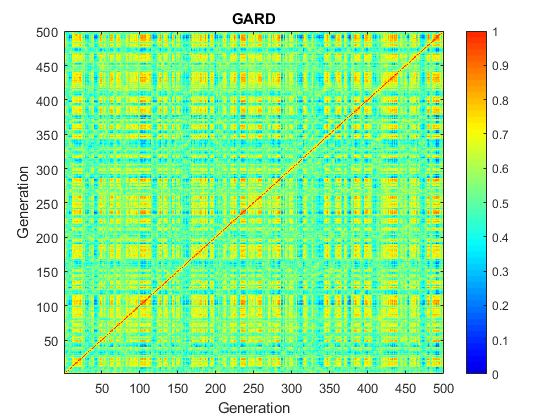

o=tgs_agard_v10(p, 1);
c=tgs_carpet(o.trace); title('GARD'); xlabel('Generation'); ylabel('Generation');

## Biased GARD simulation

ob = biased_gard_v10(p, 1.1, 1);

## Population GARD simulation

% Takes a long time to run
p.gen = 50;
opop=population_gard_nmin_v10(p, 2000);

## Population selection GARD

opopb=population_gard_nmin_v10(p, 2000, trgt);

## Mutual catalysis power of this beta network

pmc=pmc_beta_v10(o.Beta);
[timearray, ctnorm] = correlate_carpet_v10(o.trace, [], 1);
exp1=omer_curvefit_v10(timearray, ctnorm);